% Code written by Dr. Ning Lu at ECE dept, North Carolina State Univiersity

% Date: July 9, 2022 

% ECE 451 Power System Analysis - A Matlab Tutorial - Complex Power Calculation (3)

At the Load node: voltage and P&Q are given.

clear all
close all

V_rms = 120;
V_angle = 0; %<------ reference
f = 60;
w = 2*pi*f;
t = [1:1:24]'; % from mid night to mid night

% phasor representation of voltage
% V = V_rms * (cos(deg2rad(V_angle)) + 1j*sin(deg2rad(V_angle)));
V = V_rms * (cosd(V_angle) + 1j*sind(V_angle));
fprintf('Voltage in the Rectangular Form: %f%+fj\n', real(V), imag(V))

Voltage in the Rectangular Form: 120.000000+0.000000j


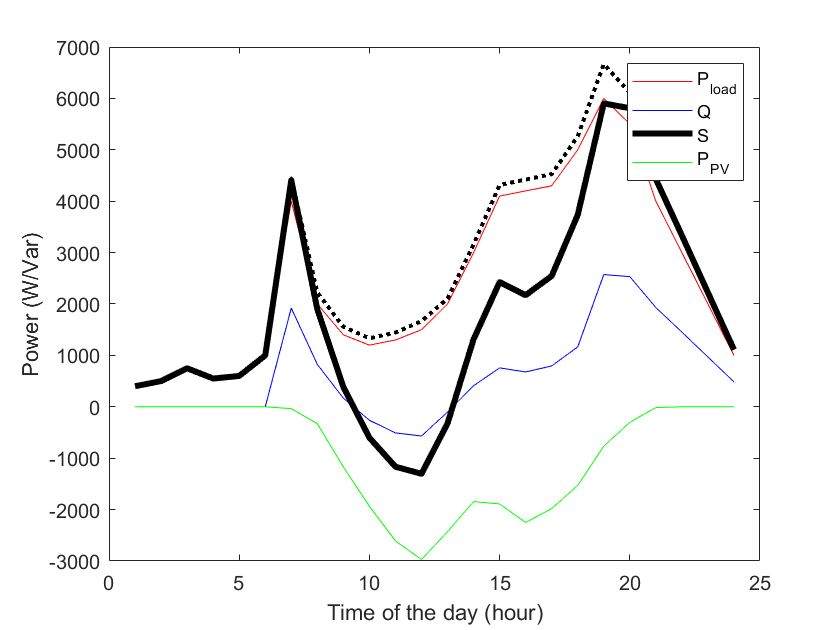

% Method 3: PQ is known
caseno = 2;
% 24 hour loads
P_load = [0.4; 0.5; 0.75; 0.55; 0.6; 1.0;  ...
         4; 2; 1.4; 1.2; 1.3; 1.5; ...
         2; 3; 4.1; 4.2; 4.3; 5; ...
         6; 5.5; 4; 3; 2; 1 ]*1000;

if caseno == 1
    P_PV = 0*ones(24,1);
elseif  caseno == 2
    P_PV = [0	0	0	0	0	0 ...
            0.0079	0.073	0.26	0.43	0.58	0.66 ...
        	0.54	0.41	0.42	0.5	0.44	0.34 ...
        	0.17	0.067	0.0032	0	0	0]'*4500;
else
    error('caseno should be either 1 or 2')
end

PowerFactor = [1.0*ones(6,1); ...
      0.9*ones(6,1); ...
      0.95*ones(6,1); ...
      0.9*ones(6,1);];
% PowerFactor = [1.0*ones(24,1)];

S = P_load./PowerFactor - P_PV;
S_load = P_load./PowerFactor;
Q = S.*(sqrt(1-PowerFactor.^2));


figure(1)
plot(t, P_load,'r')
hold on
plot(t, Q,'b')
plot(t, S, 'k','LineWidth', 3)
plot(t, -P_PV,'g')
plot(t, S_load,'k:','LineWidth', 2)
hold off
xlabel('Time of the day (hour)'), ylabel('Power (W/Var)')
legend('P_{load}','Q', 'S','P_{PV}')

Note that if power factor is low, we need to provide not only the real power from the main grid, but also the reactive power.  Thus the magnitude of the current is higher compared with providing only the real current. This is the main reason, we want to perform reactive power compensation - provide the reactive power locally by adding capacitors in the circuit.

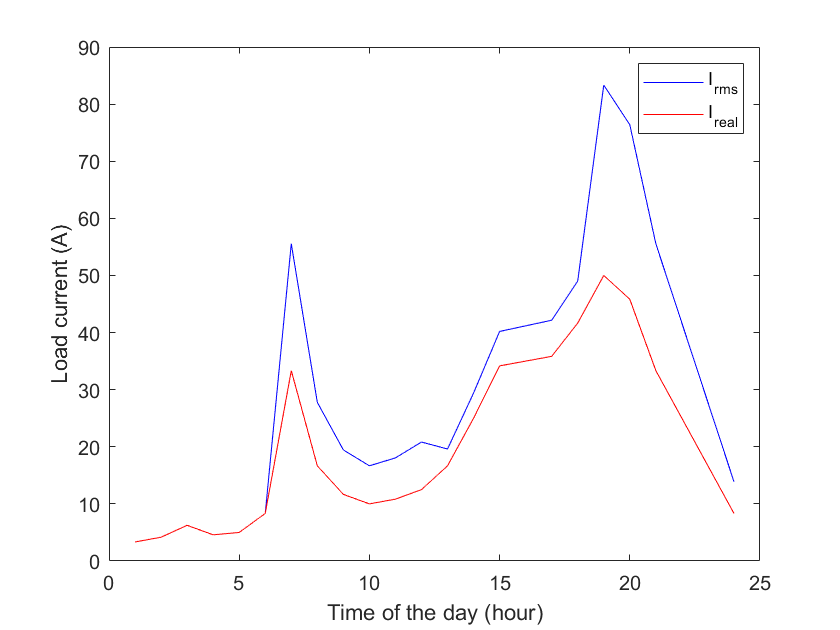

I = zeros(24,1);S = zeros(24,1);
I_rms = zeros(24,1);I_real = zeros(24,1);I_angle = zeros(24,1);

% Calculate the current for each hour
for i = 1:1:24 %length(t)
    I(i) = conj(P_load(i) + 1j*Q(i) - P_PV(i))/V;
    I_rms(i) = abs(I(i));
    I_angle(i) = rad2deg(angle(I(i)));
    I_real(i) = I_rms(i)*cosd(I_angle(i));
end

figure(2)
plot(t, I_rms,'b')
hold on
plot(t, I_real,'r')
xlabel('Time of the day (hour)'), ylabel('Load current (A)')
legend('I_{rms}','I_{real}')

Calculate the voltage droP_loadfrom the secondary side of the transformer to the point of connection of the load.  

Assume that the voltage at the transformer secondary side is maintained at 120 V

When a load is connected to the transformer through a lead line with impedance Z_line, 

Compute the voltage at the load bus.

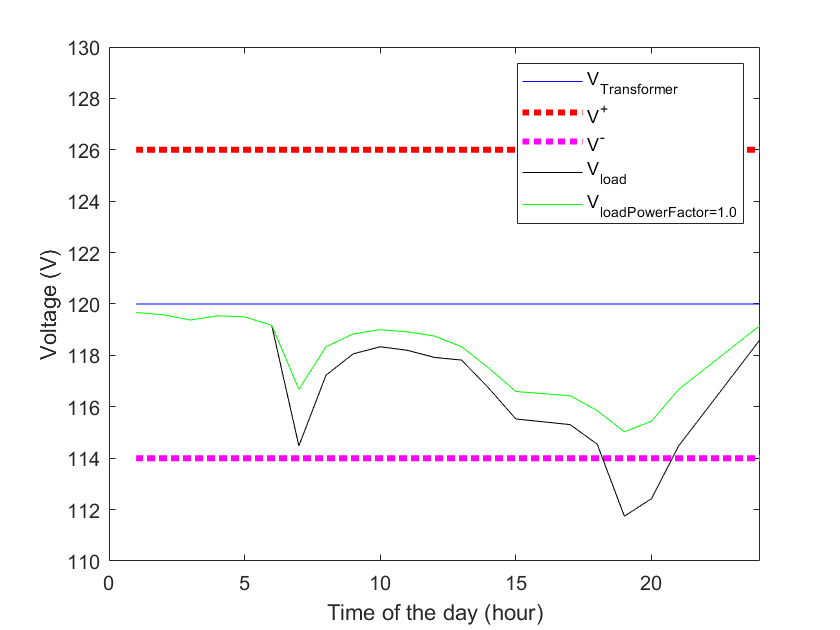

V_uplim = 120*1.05 * ones(24,1); %Voltage upper limit
V_lowlim = 120*0.95 * ones(24,1); %Voltage lower limit
Z_line = 0.1 + 0.05*1j; %Impedance of the line between Transformer and load
V_transformer = V * ones(24,1);
V_load = V - I*Z_line;
V_load_PowerFactor1 = V - I_real*Z_line;

figure(3)
plot(t, abs(V_transformer),'b')
hold on 
plot(t, abs(V_uplim),'r:','LineWidth', 3)
plot(t, abs(V_lowlim),'m:','LineWidth', 3)

plot(t, abs(V_load),'k')
plot(t, abs(V_load_PowerFactor1),'g')

ylim([110 130])
xlim([0 24])
xlabel('Time of the day (hour)'), ylabel('Voltage (V)')

legend('V_{Transformer}','V^{+}','V^{-}','V_{load}','V_{loadPowerFactor=1.0}')